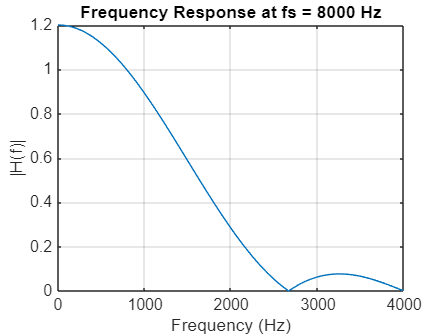

h = [0.2 0.4 0.4 0.2]; 
[H , f] = freqz(h, 1, 512, fs);
plot(f, abs(H));
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Frequency Response at fs = 8000 Hz');
grid on;



magH = abs(H);
maxH = max(magH);

cutoff_level = 0.707 * maxH;
cutoff_index = find(magH <= cutoff_level, 1, 'first');

w_c = w(cutoff_index);

fprintf('Estimated Wc = %.4f rad/sample\n', w_c);

Estimated Wc = 0.8468 rad/sample



fs1 = 8000;
fc1 = (w_c / (2*pi)) * fs1;
fs2 = 4000;
fc2 = (w_c / (2*pi)) * fs2;

fprintf('Cutoff freq at fs = 8000 Hz: %.2f Hz\n', fc1);

Cutoff freq at fs = 8000 Hz: 1078.12 Hz


fprintf('Cutoff freq at fs = 4000 Hz: %.2f Hz\n', fc2);

Cutoff freq at fs = 4000 Hz: 539.06 Hz
